# Performance of Implementations of MMM with Cache Blocking

This Live Script helps you view the performance of implementations of MMM that block for all three caches.

To make it easy to add to the graph incrementally as you implement these different routines, as you add new implementations, change the 'NO' to a 'YES'.  If the refence is to be plotted, then the top of the graph is also adjusted to the theoretical peak performance.  

clear all

plot_ref = 'YES';           % indicate if reference is to be plotted


plot_IJP = 'YES';          % you will want to copy output_IJP.m from
                           % Assignments/Week1/C/data/ to this directory

plot_JI_4x4Kernel = 'YES'; % you will want to copy output_JI_4x4Kernel.m from
                           % Assignments/Week2/C/data/ to this directory
plot_JI_12x4Kernel = 'YES';% you will want to copy output_JI_4x4Kernel.m from
                           % Assignments/Week2/C/data/ to this directory
plot_Five_Loops_4x4Kernel = 'YES';
plot_Five_Loops_12x4Kernel = 'NO';
plot_Five_Loops_Pack_4x4Kernel = 'NO';
plot_Five_Loops_Pack_12x4Kernel = 'NO';
plot_Five_Loops_Pack_12x4Kernel_OPT = 'NO';

This Life Script then creates graphs from the generated timing data.

## Load data, check accuracy, and plot timing data

turbo_clock_rate = 3.0;
flops_per_cycle = 16;
peak_gflops = turbo_clock_rate * 16;

% Create figure
figure1 = figure('Name','Figure1');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

if strcmp( plot_IJP, 'YES' )
    % Load data for IJP
    output_IJP
      
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JPI                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 1, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-', 'Color', [0 0 0] );
end

It appears all is fine



if strcmp( plot_JI_4x4Kernel, 'YES' )
    % Load data for JI_4x4Kernel
    output_JI_4x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JI_4x4Kernel             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', 'red' );
end

It appears all is fine




if strcmp( plot_JI_12x4Kernel, 'YES' )
    % Load data for JI_12x4Kernel
    output_JI_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JI_12x4Kernel         
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', '*', ...
          'LineStyle', '-.', 'Color', 'blue' );
end

It appears all is fine



if strcmp( plot_Five_Loops_4x4Kernel, 'YES' )
    % Load data for Five_Loops_4x4Kernel
    output_Five_Loops_4x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for Five_Loops_4x4Kernel           
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', 'red' );
end

It appears all is fine


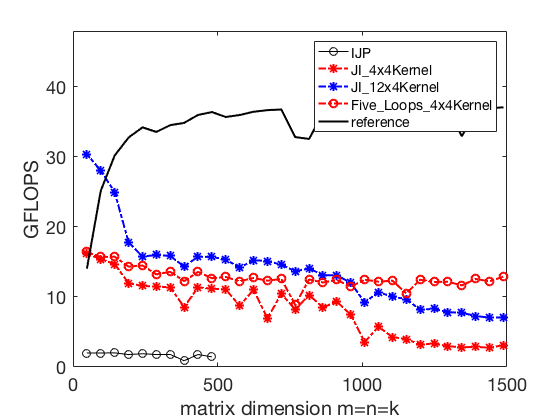


if strcmp( plot_Five_Loops_12x4Kernel, 'YES' )
    % Load data for Five_Loops_12x4Kernel
    output_Five_Loops_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for Five_Loops_12x4Kernel         
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', 'blue' );
end

if strcmp( plot_Five_Loops_Pack_4x4Kernel, 'YES' )
    % Load data for Five_Loops_Pack_4x4Kernel
    output_Five_Loops_Pack_4x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for Five_Loops_Pack_4x4Kernel           
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', 'red' );
end

if strcmp( plot_Five_Loops_Pack_12x4Kernel, 'YES' )
    % Load data for Five_Loops_Pack_12x4Kernel
    output_Five_Loops_Pack_12x4Kernel
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for Five_Loops_Pack_12x4Kernel             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', 'blue' );
end

if strcmp( plot_Five_Loops_Pack_12x4Kernel_OPT, 'YES' )
    % Load data for Five_Loops_Pack_12x4Kernel_OPT
    output_Five_Loops_Pack_12x4Kernel_OPT
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for Five_Loops_Pack_12x4Kernel_OPT             
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', Name, 'Marker', 'x', ...
          'LineStyle', '-', 'Color', 'black' );
end

if strcmp( plot_ref, 'YES' )
   % Plot time data for reference 
   plot( data(:,1), data(:,3), ...
         'MarkerSize', 8, 'LineWidth', 2, ...
         'DisplayName', 'reference', 'Color', [0 0 0] );
end

% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend1 = legend(axes1,'show');

set(legend1,'Location','northeast','FontSize',14);

if strcmp( plot_ref, 'YES' )
    % Adjust the x-axis and y-axis range to start at 0 and top of graph is peak
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
else
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
end